# Optima Bodluv

option = "";
sheetName = "blue_shot_costs";
data = importData(sheetName, option);

data.BlueEffector = replace(string(data.BlueEffector), "_", "-");

% data(data.BlueEffector == "BLUE-EF03CANNON" & data.RedTarget == "RED_PGMStandOff(GBU-39)System" & data.Outcome == "kill" & data.Scenario == "Regio", :)

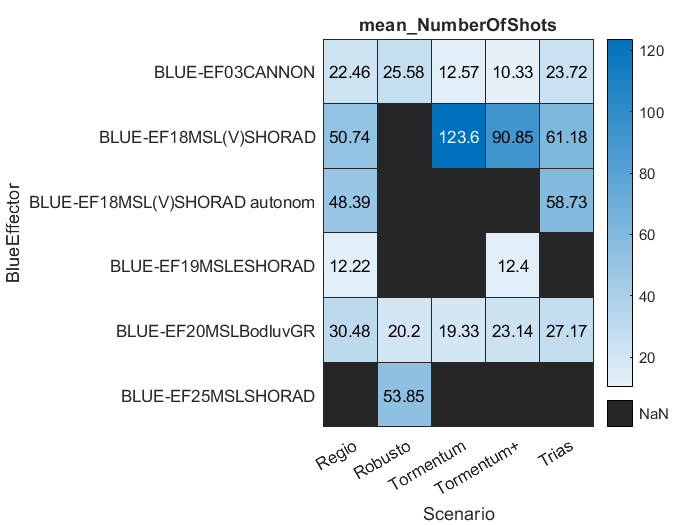

grpVar = ["Scenario"; "BlueEffector"];
dataVar = "NumberOfShots";
% statarray = statsFromData(data, grpVar, dataVar);

statarray = rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "BlueEffector"]);
statarray = rowfun(@mean, statarray, 'InputVariables', "Var5", 'GroupingVariables', ["Scenario"; "BlueEffector"]);
statarray.Properties.VariableNames{end} = ['mean_', char(dataVar)];
figure("Name", "BlueNumberOfShots"+option)
heatmap(statarray, grpVar{1}, grpVar{2}, 'ColorVariable', "mean_"+dataVar, "ColorMethod", "none");


% statarray = rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', ["Assessment"; "Scenario"; "Outcome"; "BlueEffector"]);
% statarray = rowfun(@mean, statarray, 'InputVariables', "Var6", 'GroupingVariables', ["Scenario"; "BlueEffector"]);
% statarray.Properties.VariableNames{end} = ['mean_', char(dataVar)];
% 
% figure("Name", "BlueNumberOfShots"+option)
% heatmap(statarray, grpVar{1}, grpVar{2}, 'ColorVariable', "mean_"+dataVar, "ColorMethod", "none");

function statarray = statsFromData(data, grpVar, dataVar)
	statarray = rowfun(@sum, data, 'InputVariables', dataVar, 'GroupingVariables', grpVar);
	statarray.Properties.VariableNames{end} = ['mean_', char(dataVar)];
% statarray = grpstats(MLVsu201218JEDS6(:, {grpVar, 'LED ILU iO in Prozent'}), grpVar, {'mean', 'meanci'})
% [groupMunitionslos, TID] = findgroups(MLVsu201218JEDS6.MarkMunLosNr);
% splitapply(@mean, MLVsu201218JEDS6.("LED ILU iO in Prozent"), groupMunitionslos)
end 